clear all, close all, clc % Se1_1.m.            % This is a 1D FDTD simulation of psi.

Np = 400;             % Number of points in the problem space.
hbar = 1.054e-34;     % Plank's constant
m0 = 9.1e-31;         % Free space mass of an electron
meff = 1.0;           % Effective mass: Si is 1.08, Ge is 0.067, GaAs is 0.55
m = meff*m0;      % Mass of an electron
% e = 1.6e-19;      % Charge of an electron
% epsz = 8.85e-9;       % Dielectric of free space
eV2J = 1.6e-19;       % Energy conversion factors
J2eV = 1/eV2J;

dx = 0.1e-9;        % The cell size
dt = 2e-17;           % Time steps 
ra = (0.5*hbar/m)*(dt/dx^2)  % ra must be < .15

ra = 0.1158

DX = dx*1e9;       % Cell size in nm.
XX = (1:Np)*DX;   % Length in nm for plotting

Dsquared =( diag(ones(1,Np-1),1)-2*diag(ones(1,Np))+diag(ones(1,Np-1),-1) );

## Specify the potential

V=zeros(1,Np)';% + eV2J*1e-1;
% V=[zeros(1,Np/2)+ 0.1 zeros(1,Np/2)]'*eV2J; % + 1 zeros(1,Np/2)
% V=[zeros(1,Np/2) zeros(1,Np/2)+0.1]'*eV2J;
% V=

## Initialize a sine wave in a gaussian envelope

lambda = 50; % Pulse wavelength (Ч ЫФХЛБИ ЫБЗПЧ dx)

lambda = 30;         % Pulse wavelength
sigma = 20;          % Pulse width  
nc = 150;            % Starting position  

n=(1:Np)'; 
prl=exp(-0.5*((n-nc)/sigma).^2).*cos(2*pi*(n-nc)/lambda); % The real part of the state variable
pim=exp(-0.5*((n-nc)/sigma).^2).*sin(2*pi*(n-nc)/lambda); % The imaginary part of the state variable
ptot=prl+i*pim; 
pnorm=sqrt(sum(ptot.*conj(ptot)));  % Normalization constant
% Normalize and check
prl=prl/pnorm; 
pim=pim/pnorm;
ptot=prl+i*pim; 
pnorm=sqrt(sum(ptot.*conj(ptot)))  % This should have the value 1

pnorm = 1

ans = 1.0000

T = 1

ans = 1.0000

T = 1700

ans = 1.0000

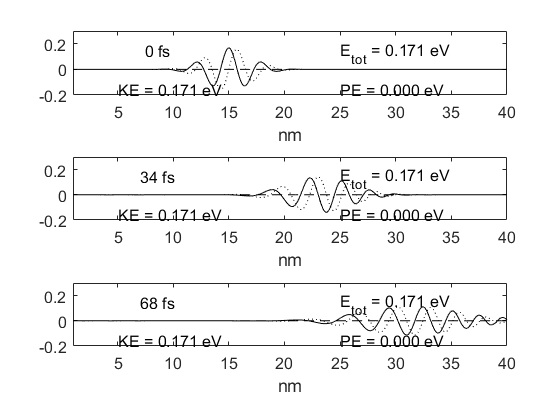

T = 3400

ans = 1.0000

Error using subplot (line 319)
Index exceeds number of subplots.

T = 0;
n_step = 1; Nstep=1;
while n_step > 0
    n_step = input('How many time steps  -->');
    % -----------This is the core FDTD program -------------
    for mm=1:n_step
        T = T + 1;
        prl   = prl   - ra*Dsquared*pim + (dt/hbar)*V.*pim;
        pim = pim + ra*Dsquared*prl   - (dt/hbar)*V.*prl;
    end
    % ------------------------------------------------------
    ptot=prl+i*pim; % Write as a complex function
    ptot'*ptot % This checks normalization
    % Calculate the expected values
    KE=J2eV*real(-(hbar/dx)^2/(2*m)*ptot'*(Dsquared*ptot)); % Kinetic energy
    PE=J2eV*ptot'*(V.*ptot); % Potential energy

    subplot(3,1,Nstep)
    plot(XX,prl,'k') 
    hold on
    plot(XX,pim,':k')
    plot(XX,J2eV*V,'--k')
    hold off
    axis( [ 1 DX*Np -.2 .3 ])
    TT = text(5,.15,sprintf('%7.0f fs',T*dt*1e15));
    set(TT,'fontsize',12)
    TT = text(5,-.15,sprintf('KE = %5.3f eV',KE));
    set(TT,'fontsize',12)
    TT = text(25,-.15,sprintf('PE = %5.3f eV',PE));
    set(TT,'fontsize',12)
    TT = text(25,.13,sprintf('E_t_o_t = %5.3f eV',KE+PE));
    set(TT,'fontsize',12)
    xlabel('nm')
    set(gca,'fontsize',12)
%     title('Se1-1')
    %grid on
    T
    Nstep=Nstep+1;
    % saveas(gcf,'se.png')      % This saves the picture to a file
end